%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path



clearvars %clear all variables
%clear all % clear all, men forsinker koden om den kjøres hver gang
% clf %clear all figures
% cla %clear all axis






# Komplekse tall

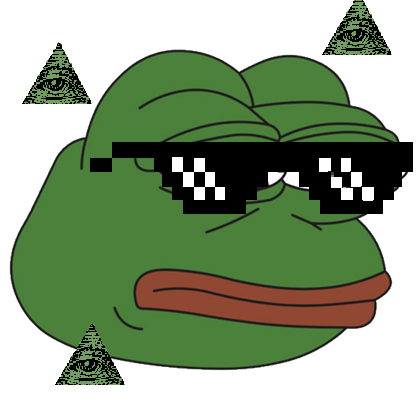

**Velg type evaluering**

typeEvaluering = 2;
 

**Evaluer et komplekst uttrykk**

Eksempel: 1/i-(1-i)/(1+i)

if typeEvaluering == 1
    z = i+eulersFormula(3,-90)+(2-i)/i
    theta = sym(angle(z)); % Finner vinkel theta
    thetaDegrees = rad2deg(theta); % Vinkel theta i grader
    r = sym(abs(z)); % Modulus, absoluttverdi, r
    
    
    zConj = conj(z)
    zDivByZConj = z/zConj
    zTimesZConj = z*zConj
    expFormExponent = (1i*theta); % Finner den eksponentielle delen av eksponentiell form. S338 i Engineering Mathematic.
    if theta ~= 0
        displayFormula(["'Eksponentiell form = e^('", string(expFormExponent),"')'"])       
    end
    disp(func2link(z))
end

**Evaluer en kompleks likning**

Eksempel: @(z) z^3==1

if typeEvaluering == 2

    
    
    syms z
    zEqn = "@(z) z^4==-1";
    zEqn = str2func(zEqn);
    disp(zEqn);
    z = solve(zEqn,z)

    theta = sym(angle(z)); % Finner vinkel theta i radianer
    thetaDegrees = rad2deg(theta); % Vinkel theta i grader
    r = sym(abs(z)); % Modulus, absoluttverdi, r
    
    zConj = conj(z)
    zDivByZConj = z./zConj
    zDivByZConjDouble = double(z./zConj)
    zTimesZConj = z.*zConj
    zTimesZConjDouble = double(z.*zConj)
    sumOfZs = sum(z)
end

    @(z)z^4==-1



$$z = \left(\begin{array}{c} \sqrt{2}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right) \end{array}\right)$$

$$zConj = \left(\begin{array}{c} \sqrt{2}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) \end{array}\right)$$

$$zDivByZConj = \left(\begin{array}{c} \mathrm{i}\\ -\mathrm{i}\\ -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

zDivByZConjDouble =    0.0000 + 1.0000i
   0.0000 - 1.0000i
   0.0000 - 1.0000i
   0.0000 + 1.0000i


$$zTimesZConj = \left(\begin{array}{c} 1\\ 1\\ 1\\ 1 \end{array}\right)$$

zTimesZConjDouble =      1
     1
     1
     1


$$sumOfZs = 0$$

**Cartesian Argand**

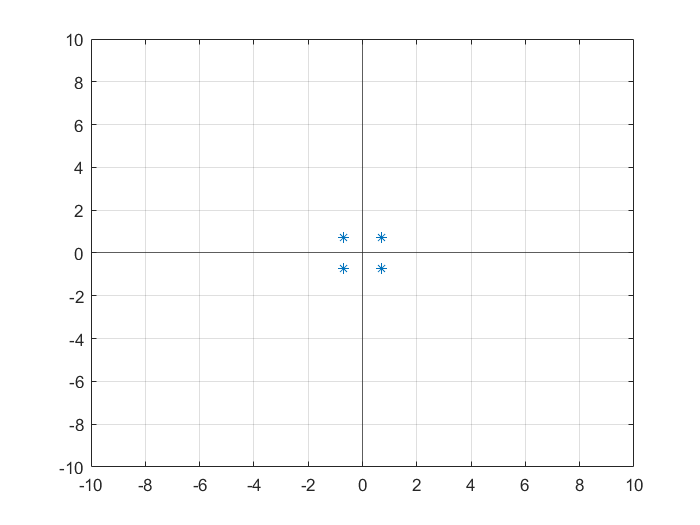

realPart = real(z);
imagPart = imag(z);
clf
cla

syms x y(x)
if typeEvaluering == 1
    quiver(0,0,realPart,imagPart,0, 'color', 'red')
    hold on
    axis([-10 10 -10 10]) % sett denne manuelt om zoomen blir feil
    yline(0)
    xline(0)
    grid on
    hold off
end

if typeEvaluering == 2
    plot(z,'*')
    hold on
    axis([-10 10 -10 10]) % sett denne manuelt om zoomen blir feil
    yline(0)
    xline(0)
    grid on
    hold off
end

**Polar Argand**

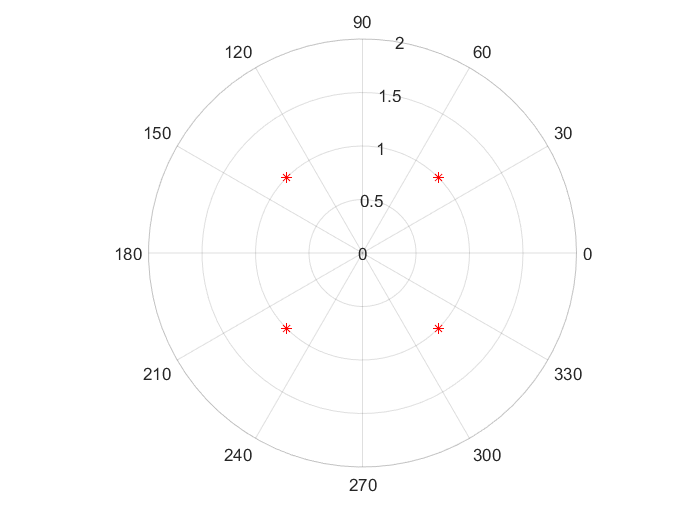

polarplot(z,'*',"Color",'red')
rlim('auto') % hent denne verdien fra funksjonen

display(theta);

$$theta = \left(\begin{array}{c} -\frac{3\,\pi }{4}\\ \frac{3\,\pi }{4}\\ -\frac{\pi }{4}\\ \frac{\pi }{4} \end{array}\right)$$

display(thetaDegrees);

$$thetaDegrees = \left(\begin{array}{c} -135\\ 135\\ -45\\ 45 \end{array}\right)$$

display(r);

$$r = \left(\begin{array}{c} 1\\ 1\\ 1\\ 1 \end{array}\right)$$

% displayFormula(["'Vinkel theta  =  '", string(theta), "' radianer  =  '", string(thetaDegrees), "' grader.'"]);
% displayFormula(["'Modulus r = '", string(r)])